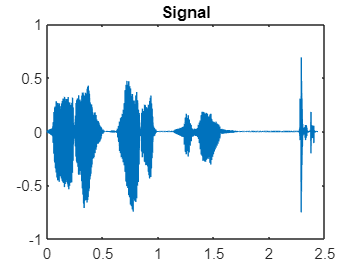

clc;
close all;
clear all;

% [y,fs] = audioread('Telugu.wav');
% [y_,fs] = audioread('Tamil.wav');
% y = y_(:,1);
% [y,fs] = audioread('Hindi.wav');
[y_,fs] = audioread('Malayali.wav');
y = y_(:,1);
t = (0:size(y,1)-1)/fs;

plot(t,y);
title("Signal")

## Change in F0

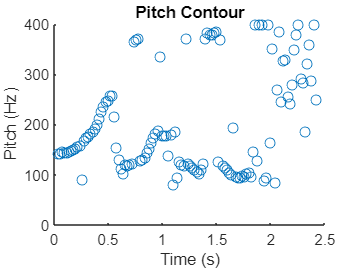



winLength = 0.04*fs;
overlapLength = round(0.02*fs);
[f,idx] = pitch(y,fs,Method="SRH",WindowLength=winLength,OverlapLength=overlapLength);
tf = idx/fs;

hr = harmonicRatio(y,fs,Window=hamming(winLength,"periodic"),OverlapLength=overlapLength);
threshold = 0.9;
f0(hr < threshold) = nan;

scatter(tf,f)
xlabel("Time (s)")
ylabel("Pitch (Hz)")
title("Pitch Contour")


avg_val = mean(f)

avg_val = 203.3250

## Distance of F0 peak with respect to VOP

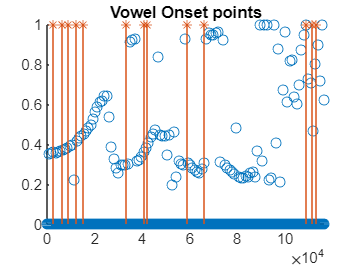



N = length(y);
q=18;
%% filtfilting
p=4000/q;
x(1,:)=bandpass(y(:,1),[15 p],fs);
for i=2:q
    x(i,:)=bandpass(y(:,1),[(i-1)*p i*p],fs);
end
%% half wave rectifier
for i=1:q
    for j=1:N
        if x(i,j)<0
            a(i,j)=0;
        else
            a(i,j)=x(i,j);
        end
    end
end
%% Lowpass filtfilt
for i=1:q
    lp(i,:)=lowpass(a(i,:),28,fs,'Steepness',0.95);
%     lp(i,:)=smooth(lp(i,:),50*fs/1000);
end
%% normalise
for i=1:q
    dw(i,:)=lp(i,:)./max(lp(i,:));
end
%% fft window
ham=hamming(20);
for i=1:q

    temp=dw(i,:);
    temp=buffer(temp,20,19);
    
    temp=temp.*(ham*ones(1,length(temp)));
    
    temp=fft(temp,40);
    
    temp = sum(abs(temp(4:16,:)));
    
    temp1(i,:)=temp;
    
end
temp1=sum(temp1);

temp1=resample(temp1,80,fs);
temp1=resample(temp1,fs,80);
temp1=temp1/max(temp1);

%% enhancement
temp1=filtfilt(hamming(1600),1,temp1);
y1=diff(temp1);
y2=buffer(y1,160,159);

y3=sum(y2);

y4=y3;

y4(y3<0)=0;

Fogd=diff(gausswin(800));

y5=filter(Fogd,1,y4);

%{
subplot(311)
plot(y4);
subplot(312)
plot(Fogd); 
subplot(313); 
plot(y5);
%}

%% Enhancing the VOP and removing close peaks and ploting it with speech signal

y5=y5./max(y5);
y5(y5<0)=0;
y5(y5<0.1)=0;

% y5=smooth(y5,320);
[pks, vop]=findpeaks(y5);


val = zeros(1,length(y));

j=1;

check = ceil(length(y)/length(f));

for i = 1:length(y)

    if mod(i,check)==0
        val(i) = f(j);
        j=j+1;
    end

end

t_ = 1:length(val);

scatter(t_,val/400)
hold on
stem(vop,ones(size(pks)),'*')
title('Vowel Onset points')

figure



## Amplitude Tilt



%% Amplitude tilt is (Ar-Af)/(Ar+Af)



## Duration Tilt



%% Duration tilt is (Dr-Df)/(Dr+Df)



## Distance between successive VOP



%% Can be seen from part 2



## Duration of Voiced region

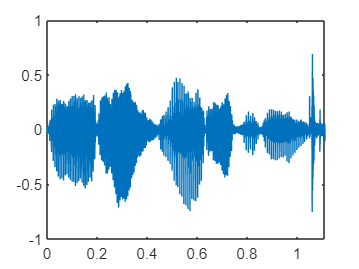



sig=y.*y;
E=mean(sig);
Threshold=0.05*E;
k=1;
for b=1:100:(length(sig)-100)
if((sum(sig(b:b+100)))/100 > Threshold)
       dest(k:k+100)=y(b:b+100);
       k=k+100;
end
end

t_v = 1/fs:1/fs:length(dest)/fs;

plot(t_v,dest);

## Change in log energy in voiced region



sum_val = dest.*dest;
Energy = sum(sum_val);
log_Energy = log(Energy)

log_Energy = 6.5610